# **DWT**

clc;
clear all; 
close all;

features_dwt = [];

for i = 1:2400
    
    image = imread(sprintf('(%d).png', i));
    
    if size(image, 3) > 1
        image = rgb2gray(image);
    end

    new = imresize(image,[256,256]);
    
    % Perform DWT decomposition
    [cA, cH, cV, cD] = dwt2(new, 'db4');
    
    % Concatenate the sub-bands into a single feature vector
    A = [cA;cH;cV;cD];
    
    % Calculate the variance of the feature vector
    B = var(A, 0, 2);

    % Append the feature vector to the overall matrix
    features_dwt = [features_dwt; B'];
end

features_dwt

features_dwt = 1.0e+04 *

    0.1118    0.0675    0.0484    0.0575    0.0919    0.1210    0.1053    0.0868    0.0883    0.0965    0.1013    0.1187    0.1613    0.1181    0.3209    0.7276    1.2545    1.7734    2.0437    2.2219    2.3582    2.3391    2.3595    2.3858    2.3161    2.3661    2.3789    2.3180    2.3545    2.3311    2.3104    2.3651    2.3729    2.2613    2.1758    2.2372    2.3013    2.3490    2.2871    2.2557    2.1647    2.2801    2.2316    2.2621    2.1522    2.1225    2.0890    1.9735    2.1285    2.1655
    0.1899    0.2116    0.1320    0.1762    0.2107    0.1763    0.5266    0.8451    1.1004    1.3132    1.4014    1.4006    1.3929    1.4190    1.7140    1.7427    1.6817    1.6872    1.6978    1.6140    1.5886    1.5562    1.5003    1.4345    1.5188    1.4607    1.4766    1.5541    1.5658    1.6273    1.6157    1.5927    1.5134    1.5916    1.6440    1.5921    1.5311    1.6467    1.6444    1.5615    1.5146    1.4747    1.4329    1.3547    1.3019    1.2841    1.3226   

# **DCT**

features_dct = [];

for i = 1:2400
    
    image = imread(sprintf('(%d).png', i));
    
    if size(image, 3) > 1
        image = rgb2gray(image);
    end
    
    new = imresize(image,[256,256]);
    
    % Perform DCT
    A = dct2(new);
    
    % Calculate the variance of the DCT coefficients
    B = var(A, 0, 2);

    % Append the feature vector to the overall matrix
    features_dct = [features_dct; B'];
end

features_dct

features_dct = 1.0e+07 *

    0.6036    0.0017    0.0396    0.0013    0.0242    0.0021    0.0070    0.0019    0.0027    0.0015    0.0016    0.0015    0.0016    0.0010    0.0012    0.0008    0.0010    0.0008    0.0006    0.0005    0.0005    0.0004    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0004    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0001    0.0002    0.0002    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7441    0.0054    0.0182    0.0048    0.0087    0.0032    0.0074    0.0017    0.0030    0.0034    0.0019    0.0011    0.0016    0.0015    0.0015    0.0007    0.0007    0.0007    0.0008    0.0006    0.0004    0.0006    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001   


% Calculate the mean of the matrix
mean_val_dct = mean(features_dct(:))

mean_val_dct = 3.1518e+04


% Add padding to the matrix
features_dct = padarray(features_dct, [0 134], mean_val_dct, 'both');

features_dct

features_dct = 1.0e+07 *

    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032
    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032   

# **DRLBP**

features_drlbp = [];

for i = 1:2400
    
    image = imread(sprintf('(%d).png', i));
    
    if size(image, 3) > 1
        image = rgb2gray(image);
    end
    
    new = imresize(image,[256,256]);
    
    % Extract the DRLBP features
    drlbp = extractLBPFeatures(new);

    % Append the feature vector to the overall matrix
    features_drlbp = [features_drlbp; drlbp];

end

features_drlbp

features_drlbp = 2400×59 single matrix
    0.3038    0.0670    0.0104    0.1050    0.0089    0.0672    0.0103    0.1020    0.0089    0.0274    0.0390    0.0395    0.0322    0.0308    0.0389    0.0362    0.0317    0.0692    0.0390    0.0681    0.0366    0.0738    0.0432    0.0678    0.0365    0.0651    0.0597    0.0752    0.0854    0.0698    0.0630    0.0738    0.0817    0.0558    0.0504    0.0490    0.0547    0.0720    0.0485    0.0500    0.0498    0.0408    0.0323    0.0350    0.0432    0.0408    0.0343    0.0317    0.0402    0.0232
    0.3266    0.1174    0.0139    0.0585    0.0120    0.1133    0.0110    0.0583    0.0111    0.0343    0.0297    0.0297    0.0325    0.0329    0.0367    0.0304    0.0359    0.0652    0.0369    0.0634    0.0389    0.0638    0.0349    0.0638    0.0385    0.0653    0.0710    0.0707    0.0797    0.0691    0.0646    0.0864    0.0744    0.0557    0.0525    0.0548    0.0586    0.0527    0.0538    0.0551    0.0490    0.0327    0.0353    0.0397    0.0404    0.0357


% Find the indices of the NaN values in the features_seak matrix
indices_drlbp = find(isnan(features_drlbp))


indices_drlbp =

  0×1 empty double column vector




% Replace the NaN values with 0
features_drlbp(indices_drlbp) = 0;

% Calculate the mean of the matrix
mean_val_drlbp = mean(features_drlbp(:))

mean_val_drlbp = single
0.0789


% Add padding to the matrix
features_drlbp = padarray(features_drlbp, [0 233], mean_val_drlbp, 'both');

features_drlbp(:,1) = [];

features_drlbp

features_drlbp = 2400×524 single matrix
    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789
    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.0789    0.078

# **Shannon Entropy Along Kurtosis Features**

features_seak = [];

for i = 1:2400
    
    image = imread(sprintf('(%d).png', i));
    
    if size(image, 3) > 1
        image = rgb2gray(image);
    end

    new = imresize(image,[256,256]);

    new_dbl = double(new);

    % Calculate the kurtosis
    k = kurtosis(new_dbl);
    
    % Calculate the Shannon entropy
    H = entropy(new(:));
    
    % Concatenate kurtosis and entropy into a final feature vector
    final_vector = (H*k);
     
    % Append the feature vector to the overall matrix
    features_seak = [features_seak; final_vector];

end

features_seak

features_seak = 1.0e+03 *

    0.0202    0.0232    0.0204    0.0169    0.0145    0.0171    0.0184    0.0193    0.0182    0.0201    0.0234    0.0432    0.0428    0.0310    0.0231    0.0203    0.0189    0.0160    0.0144    0.0136    0.0121    0.0108    0.0100    0.0099    0.0095    0.0093    0.0094    0.0090    0.0089    0.0089    0.0089    0.0093    0.0093    0.0092    0.0093    0.0095    0.0100    0.0101    0.0104    0.0104    0.0106    0.0113    0.0114    0.0121    0.0128    0.0132    0.0133    0.0135    0.0139    0.0150
    0.0280    0.0258    0.0238    0.0226    0.0237    0.0222    0.0174    0.0162    0.0177    0.0157    0.0166    0.0177    0.0139    0.0165    0.0352    0.0240    0.0174    0.0144    0.0127    0.0117    0.0112    0.0107    0.0102    0.0099    0.0095    0.0092    0.0089    0.0087    0.0088    0.0089    0.0091    0.0096    0.0101    0.0105    0.0110    0.0113    0.0112    0.0118    0.0126    0.0127    0.0131    0.0132    0.0130    0.0135    0.0133    0.0125    0.0119  


% Find the indices of the NaN values in the features_seak matrix
indices_seak = find(isnan(features_seak))

indices_seak =       611164
      612060
      613514
      613516
      613564



% Replace the NaN values with 0
features_seak(indices_seak) = 0;

% Calculate the mean of the matrix
mean_val_seak = mean(features_seak(:))

mean_val_seak = 21.7153


% Add padding to the matrix
features_seak = padarray(features_seak, [0 134], mean_val_seak, 'both');

features_seak

features_seak = 1.0e+03 *

    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217
    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217  

X1 = features_dwt/10^4;
X2 = features_dct/10^7;
X3 = features_drlbp;
X4 = features_seak/10^3;

% Initialize variables to store the maximum covariance and the corresponding pair of features
max_cov = -inf;
best_pair = [];

% Compute the pairwise covariance between all the individual sets of features
for i = 1:4
    for j = i+1:4
        % Select the pair of features
        feature1 = eval(['X' num2str(i)]);
        feature2 = eval(['X' num2str(j)]);
        
        % Compute the covariance
        cov_mat = cov(feature1,feature2);
        cov_val = cov_mat(1,2);
        
        % Update the maximum covariance and the corresponding pair of features if necessary
        if cov_val > max_cov
            max_cov = cov_val;
            best_pair = [feature1, feature2];
        end
    end
end

% The fused features are now stored in the matrix "best_pair"
best_pair

best_pair =     0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032
    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0


% best_pair = [X2, X4]

best_pair(:,1:134) = [];

best_pair(:,257:524) = [];

best_pair(:,513:646) = [];

best_pair

best_pair =     0.6036    0.0017    0.0396    0.0013    0.0242    0.0021    0.0070    0.0019    0.0027    0.0015    0.0016    0.0015    0.0016    0.0010    0.0012    0.0008    0.0010    0.0008    0.0006    0.0005    0.0005    0.0004    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0004    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0001    0.0002    0.0002    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7441    0.0054    0.0182    0.0048    0.0087    0.0032    0.0074    0.0017    0.0030    0.0034    0.0019    0.0011    0.0016    0.0015    0.0015    0.0007    0.0007    0.0007    0.0008    0.0006    0.0004    0.0006    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0

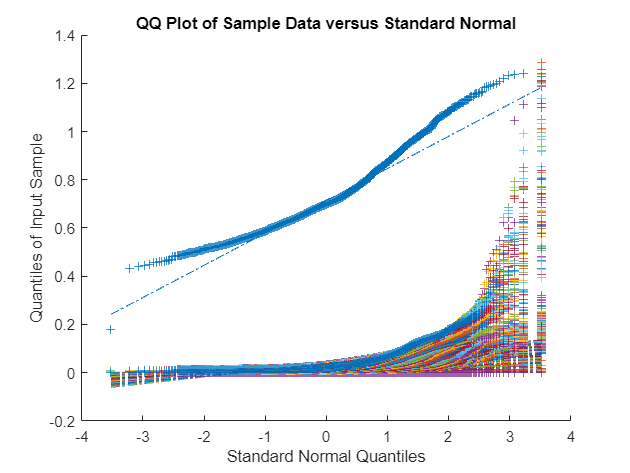


qqplot(best_pair);

# **Labels**

labels = zeros(2400,1)

labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


labels(1:100,:) = 1;
labels(201:300,:) = 1;
labels(401:500,:) = 1;
labels(601:700,:) = 1;
labels(801:900,:) = 1;
labels(1001:1100,:) = 1;
labels(1301:1400,:) = 1;
labels(1501:1600,:) = 1;
labels(1701:1800,:) = 1;
labels(1901:2000,:) = 1;
labels(2101:2200,:) = 1;
labels(2301:2400,:) = 1;

labels

labels =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% Define the fitness function
fitness = @(x) your_fitness_function(x, best_pair);

% Define the number of particles and iterations
n = 100;
iter = 100;

% Define the PSO parameters (inertia weight, cognitive and social acceleration constants)
w = 0.7;
c1 = 1.5;
c2 = 1.5;

% Initialize the particles and their velocities
x = rand(n, size(best_pair,2));
v = rand(n, size(best_pair,2));

% Initialize the best position and best fitness of each particle
pbest = x;
pbest_fitness = zeros(n,1);
for i = 1:n
    pbest_fitness(i) = fitness(pbest(i,:));
end

% Initialize the global best position and global best fitness
gbest = pbest(1,:);
gbest_fitness = pbest_fitness(1);

% Perform the PSO iterations
for i = 1:iter
    for j = 1:n
        % Update the velocity
        v(j,:) = w*v(j,:) + c1*rand*(pbest(j,:)-x(j,:)) + c2*rand*(gbest-x(j,:));
        
        % Update the position
        x(j,:) = x(j,:) + v(j,:);
        
        % Update the best position and best fitness of the particle
        curr_fitness = fitness(x(j,:));
        if curr_fitness > pbest_fitness(j)
            pbest(j,:) = x(j,:);
            pbest_fitness(j) = curr_fitness;
            
            % Update the global best position and global best fitness
            if curr_fitness > gbest_fitness
                gbest = x(j,:);
                gbest_fitness = curr_fitness;
            end
        end
    end
end

% The optimal set of features is stored in the variable "gbest"
gbest

gbest =     0.8147    0.1622    0.6443    0.0596    0.4229    0.5822    0.8507    0.5590    0.6837    0.9879    0.6312    0.7829    0.5038    0.4067    0.5038    0.1403    0.6723    0.8383    0.1982    0.1934    0.7449    0.9852    0.0560    0.1048    0.8169    0.8558    0.0499    0.4716    0.4880    0.6825    0.3796    0.9522    0.2490    0.5470    0.7175    0.7968    0.9189    0.8448    0.6306    0.8623    0.4271    0.8850    0.1253    0.5305    0.7444    0.9834    0.2940    0.0373    0.4479    0.7094


# **SVDD**

% Split the data into training and test sets
idx = randperm(2400);
train_idx = idx(1:2000);
test_idx = idx(2001:2400);

X_train = best_pair(train_idx,:);
y_train = labels(train_idx);
X_test = best_pair(test_idx,:);
y_test = labels(test_idx);

% Define the parameters for the SVDD classifier
nu = 0.05;
kernel = 'rbf';
gamma = 1;

% Train the SVDD classifier using the training set
svdd_classifier = fitcsvm(X_train, y_train, 'KernelFunction', kernel, 'KernelScale', gamma, 'BoxConstraint', 1/nu);

% Use the SVDD classifier to predict the labels of the test set
predictions_svdd = predict(svdd_classifier, X_test);

% Compute the accuracy of the classifier
acc_svdd = mean(predictions_svdd == y_test);

% Print the accuracy
fprintf('Accuracy: %f\n', acc_svdd*100);

Accuracy: 80.250000



% Compute the confusion matrix
[tn, fn, fp, tp] = confusion_matrix(y_test, predictions_svdd)

tn = 157

fn = 47

fp = 32

tp = 164


% Compute the confusion matrix
mat_svdd = confusionmat(y_test, predictions_svdd)

mat_svdd =    164    32
    47   157


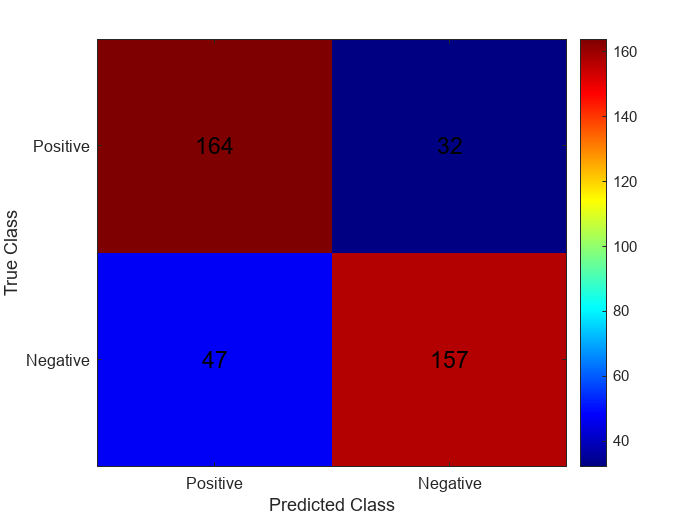


% Plot the confusion matrix
% Plot the confusion matrix
figure;
imagesc(mat_svdd);
colormap(jet);
colorbar;
xlabel('Predicted Class');
ylabel('True Class');
set(gca,'XTick',1:2);
set(gca,'YTick',1:2);
xticklabels({'Positive','Negative'});
yticklabels({'Positive','Negative'});

% Add numbers to the plot
for i = 1:size(mat_svdd,1)
    for j = 1:size(mat_svdd,2)
        text(j, i, num2str(mat_svdd(i,j)), 'HorizontalAlignment','center','Color','black', 'FontSize', 14);
    end
end

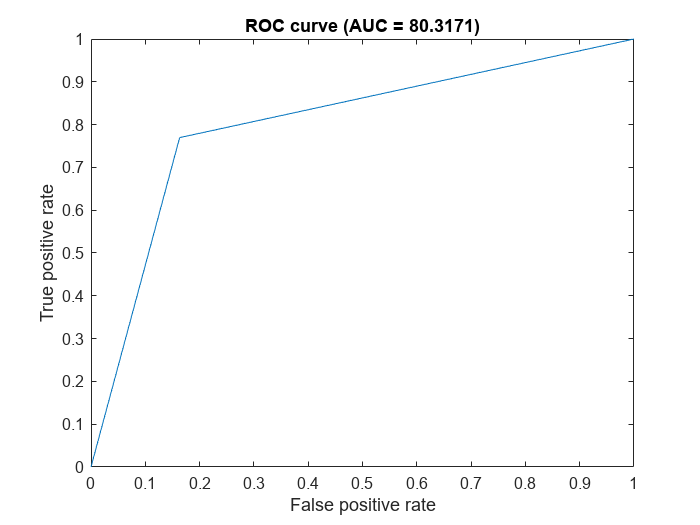


% Compute the sensitivity (true positive rate)
sensitivity_svdd = tp / (tp + fn);

% Compute the specificity (true negative rate)
specificity_svdd = tn / (tn + fp);

% Compute the precision
precision_svdd = tp / (tp + fp);

% Compute the F1-score
f1_score_svdd = 2 * (precision_svdd * sensitivity_svdd) / (precision_svdd + sensitivity_svdd);

% Compute the accuracy
accuracy_svdd = (tp + tn) / (tp + fn + fp + tn);

% Compute the FNR
fnr_svdd = fn / (tp + fn);

% Compute the AUC
[~,~,~,auc_svdd] = perfcurve(y_test, predictions_svdd, 1);

% Compute the ROC curve and AUC
[X,Y,T,AUC_svdd] = perfcurve(y_test, predictions_svdd, 1);

% Plot the ROC curve
figure;
plot(X,Y);
xlabel('False positive rate');
ylabel('True positive rate');
title(['ROC curve (AUC = ', num2str(AUC_svdd*100), ')']);


% Print the results
fprintf('Sensitivity: %f\n', sensitivity_svdd*100);

Sensitivity: 77.725118


fprintf('Specificity: %f\n', specificity_svdd*100);

Specificity: 83.068783


fprintf('Precision: %f\n', precision_svdd*100);

Precision: 83.673469


fprintf('F1-Score: %f\n', f1_score_svdd*100);

F1-Score: 80.589681


fprintf('Accuracy: %f\n', accuracy_svdd*100);

Accuracy: 80.250000


fprintf('FNR: %f\n', fnr_svdd*100);

FNR: 22.274882


fprintf('AUC: %f\n', auc_svdd*100);

AUC: 80.317127


# **KNN**

% Split the data into training and test sets
idx = randperm(2400);
train_idx = idx(1:2000);
test_idx = idx(2001:2400);

X_train = best_pair(train_idx,:);
y_train = labels(train_idx);
X_test = best_pair(test_idx,:);
y_test = labels(test_idx);

% Define the parameters for the k-NN classifier
k = 5;

% Train the k-NN classifier using the training set
knn_classifier = fitcknn(X_train, y_train, 'NumNeighbors', k);

% Use the k-NN classifier to predict the labels of the test set
predictions_knn = predict(knn_classifier, X_test);

% Compute the accuracy of the classifier
acc_knn = mean(predictions_knn == y_test);

% Print the accuracy
fprintf('Accuracy: %f\n', acc_knn*100);

Accuracy: 82.750000



% Compute the confusion matrix
[tn, fn, fp, tp] = confusion_matrix(y_test, predictions_knn)

tn = 161

fn = 36

fp = 33

tp = 170


% Compute the confusion matrix
mat_knn = confusionmat(y_test, predictions_knn)

mat_knn =    170    33
    36   161


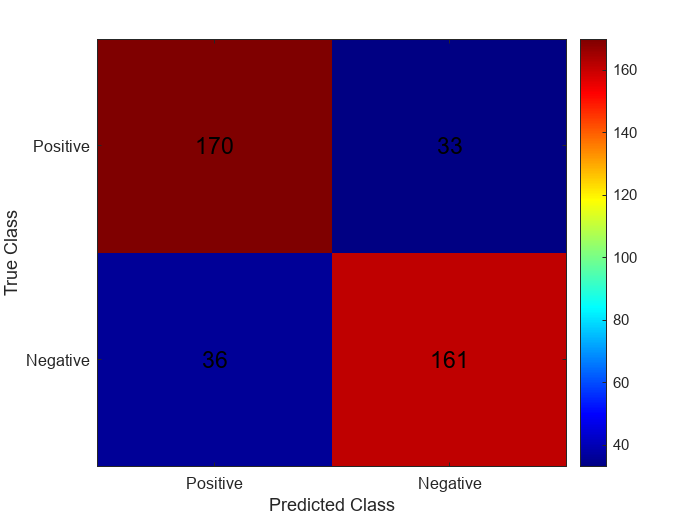


% Plot the confusion matrix
% Plot the confusion matrix
figure;
imagesc(mat_knn);
colormap(jet);
colorbar;
xlabel('Predicted Class');
ylabel('True Class');
set(gca,'XTick',1:2);
set(gca,'YTick',1:2);
xticklabels({'Positive','Negative'});
yticklabels({'Positive','Negative'});

% Add numbers to the plot
for i = 1:size(mat_knn,1)
    for j = 1:size(mat_knn,2)
        text(j, i, num2str(mat_knn(i,j)), 'HorizontalAlignment','center','Color','black', 'FontSize', 14);
    end
end

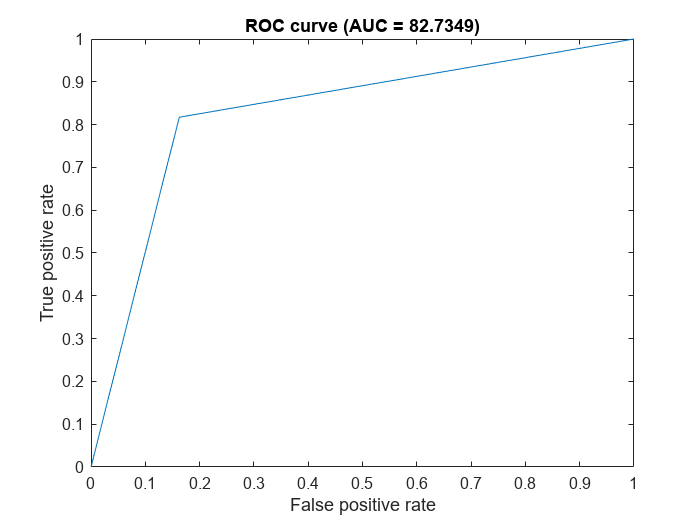


% Compute the sensitivity (true positive rate)
sensitivity_knn = tp / (tp + fn);

% Compute the specificity (true negative rate)
specificity_knn = tn / (tn + fp);

% Compute the precision
precision_knn = tp / (tp + fp);

% Compute the F1-score
f1_score_knn = 2 * (precision_knn * sensitivity_knn) / (precision_knn + sensitivity_knn);

% Compute the accuracy
accuracy_knn = (tp + tn) / (tp + fn + fp + tn);

% Compute the FNR
fnr_knn = fn / (tp + fn);

% Compute the AUC
[~,~,~,auc_knn] = perfcurve(y_test, predictions_knn, 1);

% Compute the ROC curve and AUC
[X,Y,T,AUC_knn] = perfcurve(y_test, predictions_knn, 1);

% Plot the ROC curve
figure;
plot(X,Y);
xlabel('False positive rate');
ylabel('True positive rate');
title(['ROC curve (AUC = ', num2str(AUC_knn*100), ')']); 


% Print the results
fprintf('Sensitivity: %f\n', sensitivity_knn*100);

Sensitivity: 82.524272


fprintf('Specificity: %f\n', specificity_knn*100);

Specificity: 82.989691


fprintf('Precision: %f\n', precision_knn*100);

Precision: 83.743842


fprintf('F1-Score: %f\n', f1_score_knn*100);

F1-Score: 83.129584


fprintf('Accuracy: %f\n', accuracy_knn*100);

Accuracy: 82.750000


fprintf('FNR: %f\n', fnr_knn*100);

FNR: 17.475728


fprintf('AUC: %f\n', auc_knn*100);

AUC: 82.734865


# **DT**

% Split the data into training and test sets
idx = randperm(2400);
train_idx = idx(1:2000);
test_idx = idx(2001:2400);

X_train = best_pair(train_idx,:);
y_train = labels(train_idx);
X_test = best_pair(test_idx,:);
y_test = labels(test_idx);

% Train the Decision Tree classifier using the training set
dt_classifier = fitctree(X_train, y_train);

% Use the Decision Tree classifier to predict the labels of the test set
predictions_dt = predict(dt_classifier, X_test);

% Compute the accuracy of the classifier
acc_dt = mean(predictions_dt == y_test);

% Print the accuracy
fprintf('Accuracy: %f\n', acc_dt*100);

Accuracy: 83.500000



% Compute the confusion matrix
[tn, fn, fp, tp] = confusion_matrix(y_test, predictions_dt)

tn = 159

fn = 34

fp = 32

tp = 175


% Compute the confusion matrix
mat_dt = confusionmat(y_test, predictions_dt)

mat_svdd =    175    32
    34   159


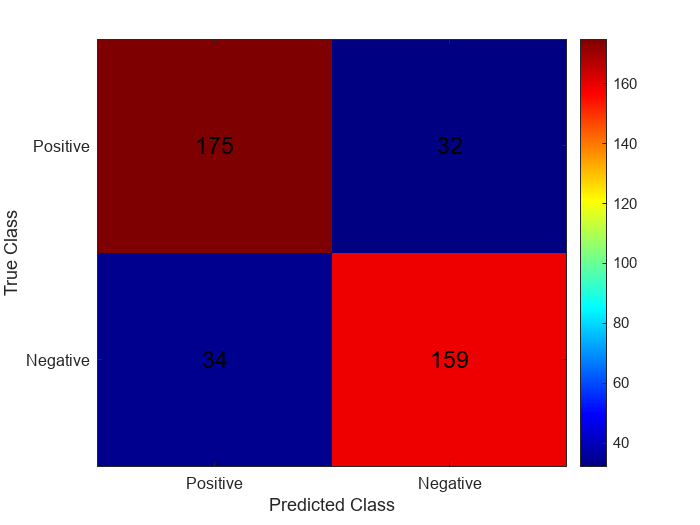


% Plot the confusion matrix
% Plot the confusion matrix
figure;
imagesc(mat_dt);
colormap(jet);
colorbar;
xlabel('Predicted Class');
ylabel('True Class');
set(gca,'XTick',1:2);
set(gca,'YTick',1:2);
xticklabels({'Positive','Negative'});
yticklabels({'Positive','Negative'});

% Add numbers to the plot
for i = 1:size(mat_dt,1)
    for j = 1:size(mat_dt,2)
        text(j, i, num2str(mat_dt(i,j)), 'HorizontalAlignment','center','Color','black', 'FontSize', 14);
    end
end

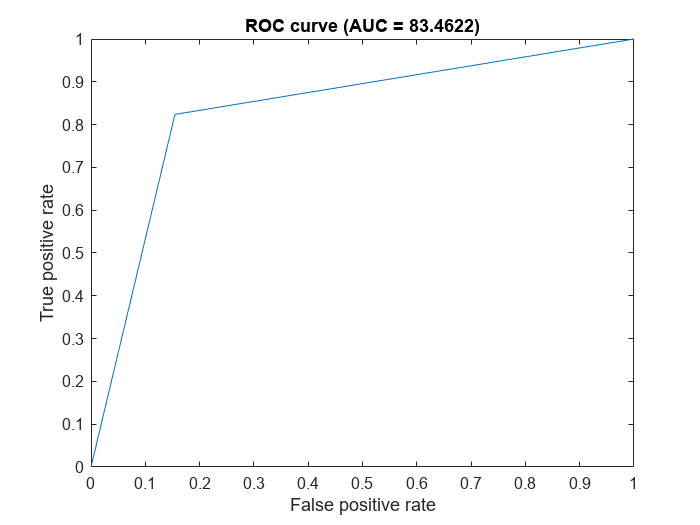


% Compute the sensitivity (true positive rate)
sensitivity_dt = tp / (tp + fn);

% Compute the specificity (true negative rate)
specificity_dt = tn / (tn + fp);

% Compute the precision
precision_dt = tp / (tp + fp);

% Compute the F1-score
f1_score_dt = 2 * (precision_dt * sensitivity_dt) / (precision_dt + sensitivity_dt);

% Compute the accuracy
accuracy_dt = (tp + tn) / (tp + fn + fp + tn);

% Compute the FNR
fnr_dt = fn / (tp + fn);

% Compute the AUC
[~,~,~,auc_dt] = perfcurve(y_test, predictions_dt, 1);

% Compute the ROC curve and AUC
[X,Y,T,AUC_dt] = perfcurve(y_test, predictions_dt, 1);

% Plot the ROC curve
figure;
plot(X,Y);
xlabel('False positive rate');
ylabel('True positive rate');
title(['ROC curve (AUC = ', num2str(AUC*100), ')']);


% Print the results
fprintf('Sensitivity: %f\n', sensitivity_dt*100);

Sensitivity: 83.732057


fprintf('Specificity: %f\n', specificity_dt*100);

Specificity: 83.246073


fprintf('Precision: %f\n', precision_dt*100);

Precision: 84.541063


fprintf('F1-Score: %f\n', f1_score_dt*100);

F1-Score: 84.134615


fprintf('Accuracy: %f\n', accuracy_dt*100);

Accuracy: 83.500000


fprintf('FNR: %f\n', fnr_dt*100);

FNR: 16.267943


fprintf('AUC: %f\n', auc_dt*100);

AUC: 83.462241


# **RF**

% Split the data into training and test sets
idx = randperm(2400);
train_idx = idx(1:2000);
test_idx = idx(2001:2400);

X_train = best_pair(train_idx,:);
y_train = labels(train_idx);
X_test = best_pair(test_idx,:);
y_test = labels(test_idx);

% Define the parameters for the Random Forest classifier
ntrees = 100;

% Train the Random Forest classifier using the training set
rf_classifier = TreeBagger(ntrees, X_train, y_train, 'Method','classification');

% Use the Random Forest classifier to predict the labels of the test set
predictions_rf = predict(rf_classifier, X_test);
predictions_rf = str2double(predictions_rf);

% Compute the accuracy of the classifier
acc_rf = mean(predictions_rf == y_test);

% Print the accuracy
fprintf('Accuracy: %f\n', acc_rf*100);

Accuracy: 92.000000



% Compute the confusion matrix
[tn, fn, fp, tp] = confusion_matrix(y_test, predictions_rf)

tn = 180

fn = 16

fp = 16

tp = 188


% Compute the confusion matrix
mat_rf = confusionmat(y_test, predictions_rf)

mat_rf =     97   107
   112    84


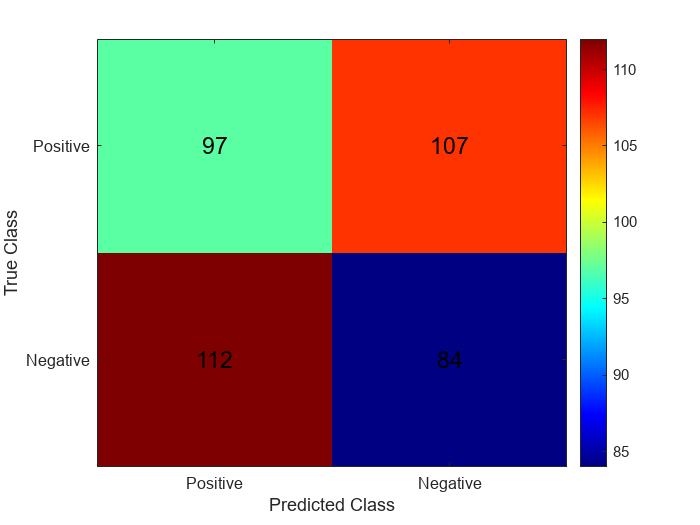


% Plot the confusion matrix
% Plot the confusion matrix
figure;
imagesc(mat_rf);
colormap(jet);
colorbar;
xlabel('Predicted Class');
ylabel('True Class');
set(gca,'XTick',1:2);
set(gca,'YTick',1:2);
xticklabels({'Positive','Negative'});
yticklabels({'Positive','Negative'});

% Add numbers to the plot
for i = 1:size(mat_rf,1)
    for j = 1:size(mat_rf,2)
        text(j, i, num2str(mat_rf(i,j)), 'HorizontalAlignment','center','Color','black', 'FontSize', 14);
    end
end

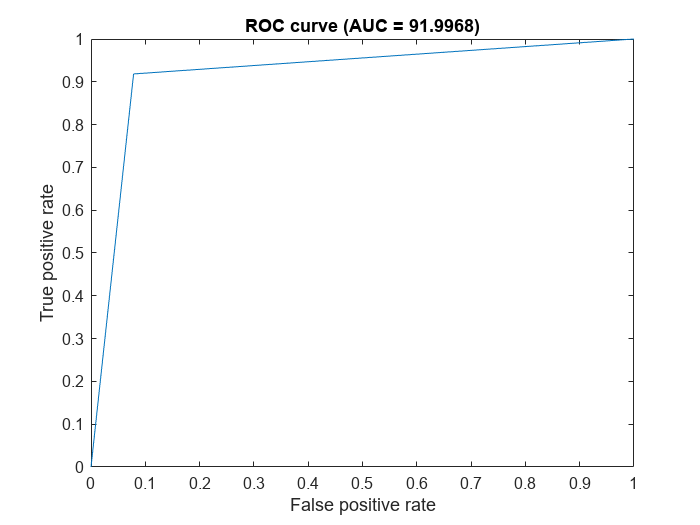


% Compute the sensitivity (true positive rate)
sensitivity_rf = tp / (tp + fn);

% Compute the specificity (true negative rate)
specificity_rf = tn / (tn + fp);

% Compute the precision
precision_rf = tp / (tp + fp);

% Compute the F1-score
f1_score_rf = 2 * (precision_rf * sensitivity_rf) / (precision_rf + sensitivity_rf);

% Compute the accuracy
accuracy_rf = (tp + tn) / (tp + fn + fp + tn);

% Compute the FNR
fnr_rf = fn / (tp + fn);

% Compute the AUC
[~,~,~,auc_rf] = perfcurve(y_test, predictions_rf, 1);

% Compute the ROC curve and AUC
[X,Y,T,AUC_rf] = perfcurve(y_test, predictions_rf, 1);

% Plot the ROC curve
figure;
plot(X,Y);
xlabel('False positive rate');
ylabel('True positive rate');
title(['ROC curve (AUC = ', num2str(AUC_rf*100), ')']);


% Print the results
fprintf('Sensitivity: %f\n', sensitivity_rf*100);

Sensitivity: 92.156863


fprintf('Specificity: %f\n', specificity_rf*100);

Specificity: 91.836735


fprintf('Precision: %f\n', precision_rf*100);

Precision: 92.156863


fprintf('F1-Score: %f\n', f1_score_rf*100);

F1-Score: 92.156863


fprintf('Accuracy: %f\n', accuracy_rf*100);

Accuracy: 92.000000


fprintf('FNR: %f\n', fnr_rf*100);

FNR: 7.843137


fprintf('AUC: %f\n', auc_rf*100);

AUC: 91.996799


# **NB**

% Split the data into training and test sets
idx = randperm(2400);
train_idx = idx(1:2000);
test_idx = idx(2001:2400);

X_train = best_pair(train_idx,:);
y_train = labels(train_idx);
X_test = best_pair(test_idx,:);
y_test = labels(test_idx);

% Train the Naive Bayes classifier using the training set
nb_classifier = fitcnb(X_train, y_train);

% Use the Naive Bayes classifier to predict the labels of the test set
predictions_nb = predict(nb_classifier, X_test);

% Compute the accuracy of the classifier
acc_nb = mean(predictions_nb == y_test);

% Print the accuracy
fprintf('Accuracy: %f\n', acc_nb*100);

Accuracy: 70.250000



% Compute the confusion matrix
[tn, fn, fp, tp] = confusion_matrix(y_test, predictions_nb)

tn = 105

fn = 103

fp = 16

tp = 176


% Compute the confusion matrix
mat_nb = confusionmat(y_test, predictions_nb)

mat_nb =    176    16
   103   105


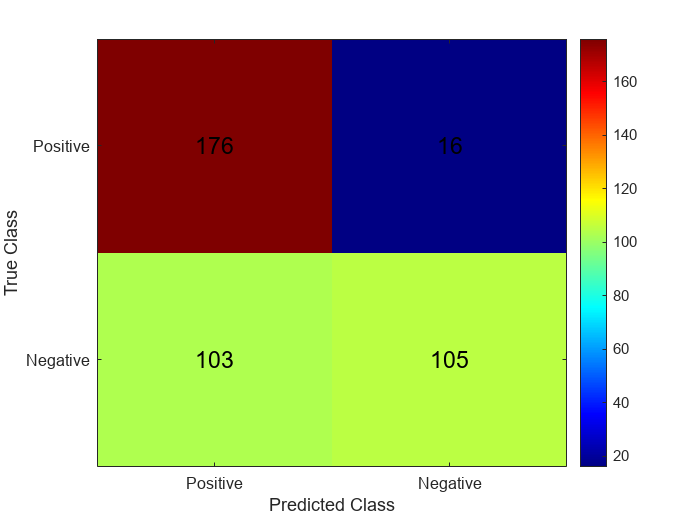


% Plot the confusion matrix
% Plot the confusion matrix
figure;
imagesc(mat_nb);
colormap(jet);
colorbar;
xlabel('Predicted Class');
ylabel('True Class');
set(gca,'XTick',1:2);
set(gca,'YTick',1:2);
xticklabels({'Positive','Negative'});
yticklabels({'Positive','Negative'});

% Add numbers to the plot
for i = 1:size(mat_nb,1)
    for j = 1:size(mat_nb,2)
        text(j, i, num2str(mat_nb(i,j)), 'HorizontalAlignment','center','Color','black', 'FontSize', 14);
    end
end

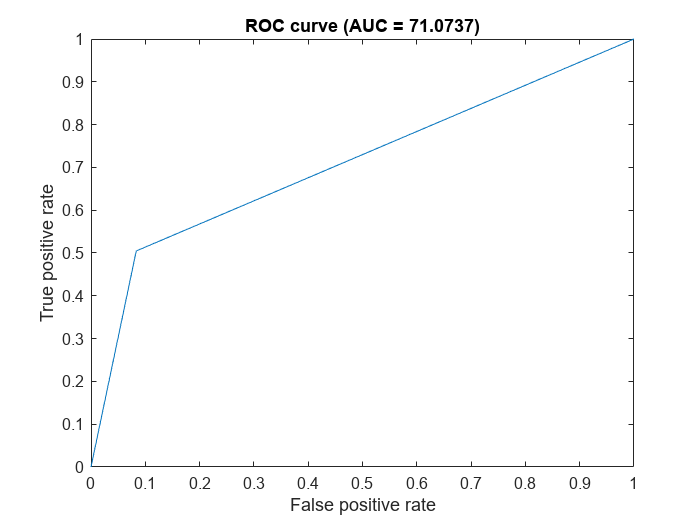

% Compute the sensitivity (true positive rate)
sensitivity_nb = tp / (tp + fn);

% Compute the specificity (true negative rate)
specificity_nb = tn / (tn + fp);

% Compute the precision
precision_nb = tp / (tp + fp);

% Compute the F1-score
f1_score_nb = 2 * (precision * sensitivity_nb) / (precision + sensitivity_nb);

% Compute the accuracy
accuracy_nb = (tp + tn) / (tp + fn + fp + tn);

% Compute the FNR
fnr_nb = fn / (tp + fn);

% Compute the AUC
[~,~,~,auc_nb] = perfcurve(y_test, predictions_nb, 1);

% Compute the ROC curve and AUC
[X,Y,T,AUC_nb] = perfcurve(y_test, predictions_nb, 1);

% Plot the ROC curve
figure;
plot(X,Y);
xlabel('False positive rate');
ylabel('True positive rate');
title(['ROC curve (AUC = ', num2str(AUC_nb*100), ')']);


% Print the results
fprintf('Sensitivity: %f\n', sensitivity_nb*100);

Sensitivity: 63.082437


fprintf('Specificity: %f\n', specificity_nb*100);

Specificity: 86.776860


fprintf('Precision: %f\n', precision_nb*100);

Precision: 91.666667


fprintf('F1-Score: %f\n', f1_score_nb*100);

F1-Score: 74.111697


fprintf('Accuracy: %f\n', accuracy_nb*100);

Accuracy: 70.250000


fprintf('FNR: %f\n', fnr_nb*100);

FNR: 36.917563


fprintf('AUC: %f\n', auc_nb*100);

AUC: 71.073718


# **Ensemble method**

% Train multiple classifiers and store them in a cell array
num_classifiers = 5;
classifiers = cell(num_classifiers,1);
for i = 1:num_classifiers
    classifiers{i} = fitcsvm(X_train, y_train, 'KernelFunction', kernel, 'KernelScale', gamma, 'BoxConstraint', 1/nu);
end

% Use the classifiers to predict the labels of the test set
predictions_ensemble = zeros(size(y_test));
for i = 1:num_classifiers
    predictions_ensemble = predictions_ensemble + predict(classifiers{i}, X_test);
end
predictions_ensemble = sign(predictions_ensemble);

% Compute the accuracy of the ensemble classifier
acc_ensemble = mean(predictions_ensemble == y_test);

% Print the accuracy
fprintf('Accuracy (Ensemble): %f\n', acc_ensemble*100);

Accuracy (Ensemble): 80.000000



% Compute the confusion matrix
[tn, fn, fp, tp] = confusion_matrix(y_test, predictions_nb)

tn = 63

fn = 134

fp = 58

tp = 145


% Compute the confusion matrix
mat_ens = confusionmat(y_test, predictions_nb)

mat_ens =    145    58
   134    63


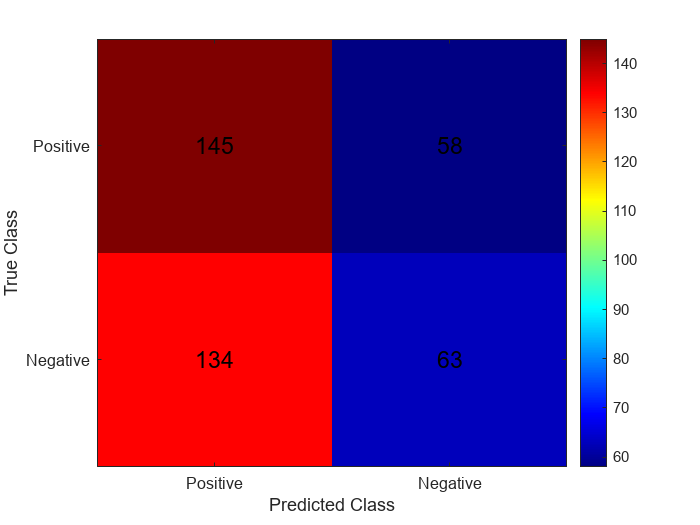


% Plot the confusion matrix
figure;
imagesc(mat_ens);
colormap(jet);
colorbar;
xlabel('Predicted Class');
ylabel('True Class');
set(gca,'XTick',1:2);
set(gca,'YTick',1:2);
xticklabels({'Positive','Negative'});
yticklabels({'Positive','Negative'});

% Add numbers to the plot
for i = 1:size(mat_ens,1)
    for j = 1:size(mat_ens,2)
        text(j, i, num2str(mat_ens(i,j)), 'HorizontalAlignment','center','Color','black', 'FontSize', 14);
    end
end


% Compute the sensitivity (true positive rate)
sensitivity_ens = tp / (tp + fn);

% Compute the specificity (true negative rate)
specificity_ens = tn / (tn + fp);

% Compute the precision
predictions_ensemble = tp / (tp + fp);

% Compute the F1-score
f1_score_ens = 2 * (predictions_ensemble * sensitivity_ens) / (predictions_ensemble + sensitivity_ens);

% Compute the accuracy
accuracy_ens = (tp + tn) / (tp + fn + fp + tn);

% Compute the FNR
fnr_ens = fn / (tp + fn);

% Compute the AUC
[~,~,~,acc] = perfcurve(y_test, predictions_ensemble, 1);

Error using perfcurve>preparedata
The size of scores does not
match the size of labels.

Error in perfcurve (line 396)
[scores,cls,weights,ncv] = preparedata(scores,cls,weights);


% Compute the ROC curve and AUC
[X,Y,T,AUC] = perfcurve(y_test, predictions_ensemble, 1);

% Plot the ROC curve
figure;
plot(X,Y);
xlabel('False positive rate');
ylabel('True positive rate');
title(['ROC curve (AUC = ', num2str(AUC*100), ')']);

% Print the results
fprintf('Sensitivity: %f\n', sensitivity_ens*100);
fprintf('Specificity: %f\n', specificity_ens*100);
fprintf('Precision: %f\n', predictions_ensemble*100);
fprintf('F1-Score: %f\n', f1_score_ens*100);
fprintf('Accuracy: %f\n', accuracy_ens*100);
fprintf('FNR: %f\n', fnr_ens*100);
fprintf('AUC: %f\n', auc_ens*100);

function acc = your_fitness_function(x, best_pair)
    % Use the selected features to train a classifier

    labels = zeros(2400,1);
    labels(1:100,:) = 1;
    labels(201:300,:) = 1;
    labels(401:500,:) = 1;
    labels(601:700,:) = 1;
    labels(801:900,:) = 1;
    labels(1001:1100,:) = 1;
    labels(1301:1400,:) = 1;
    labels(1501:1600,:) = 1;
    labels(1701:1800,:) = 1;
    labels(1901:2000,:) = 1;
    labels(2101:2200,:) = 1;
    labels(2301:2400,:) = 1;

    classifier = fitcecoc(best_pair, labels);
    % Use the classifier to predict the labels of the samples
    predictions = predict(classifier, x);
    % Compute the accuracy
    acc = mean(predictions == labels);
end

function [tp, fn, fp, tn] = confusion_matrix(y_true, y_pred)
    tp = sum((y_true == 1) & (y_pred == 1));
    fn = sum((y_true == 1) & (y_pred == 0));
    fp = sum((y_true == 0) & (y_pred == 1));
    tn = sum((y_true == 0) & (y_pred == 0));
end


% % Define the fitness function
% % In this case, we use the ELM classifier to classify the data and compute the accuracy
% fitness_func = @(x) -elm_classifier(x);
% 
% % Define the number of particles and the number of features
% num_particles = 50;
% num_features = 524;
% 
% % Define the initial position and velocity for each particle
% positions = rand(num_particles, num_features);
% velocities = rand(num_particles, num_features);
% 
% % Define the acceleration coefficients
% c1 = 2;
% c2 = 2;
% 
% % Define the inertia weight
% w = 0.9;
% 
% % Define the maximum number of iterations
% max_iterations = 100;
% 
% % Initialize the best position and fitness for each particle
% best_positions = positions;
% best_fitnesses = zeros(num_particles, 1);
% 
% % Initialize the best global position and fitness
% global_best_position = zeros(1, num_features);
% global_best_fitness = -inf;
% 
% % Perform the PSO loop
% for i = 1:max_iterations
%     % Update the position and velocity of each particle
%     for j = 1:num_particles
%         % Compute the current fitness
%         current_fitness = fitness_func(positions(j,:));
%         
%         % Update the best position and fitness for this particle if necessary
%         if current_fitness > best_fitnesses(j)
%             best_positions(j,:) = positions(j,:);
%             best_fitnesses(j) = current_fitness;
%             
%             % Update the global best position and fitness if necessary
%             if current_fitness > global_best_fitness
%                 global_best_position = positions(j,:);
%                 global_best_fitness = current_fitness;
%             end
%         end
%         
%         % Update the velocity of the particle
%         velocities(j,:) = w * velocities(j,:) + c1 * rand * (best_positions(j,:) - positions(j,:)) + c2 * rand * (global_best_position - positions(j,:));
%         
%         % Update the position of the particle
%         positions(j,:) = positions(j,:) + velocities(j,:);
%     end
% end

% % The final optimized subset of features is given by the global best position
% optimized_features = global_best_position;
% 
% % Extract the indices of the selected features
% feature_indices = find(optimized_features);
% 
% % Select the corresponding features from the original feature matrices
% X_optimized = [X1(:,feature_indices), X2(:,feature_indices), X3(:,feature_indices), X4(:,feature_indices), X5(:,feature_indices)];
% 
% % Apply the ELM classifier to the optimized features
% elm_model = elm_classifier(X_optimized);
% 
% % This elm_model can be used for further classification on unseen data
% % Define the number of trees
% num_trees = 50;
% 
% num_particles = 50;
% 
% % Define the number of features
% num_features = size(best_pair,2);
% 
% % Define the maximum number of iterations
% max_iterations = 500;
% 
% % Define the constants for the PSO algorithm
% c1 = 2;
% c2 = 2;
% w = 0.9;
% 
% velocities = zeros(num_particles,num_features);
% 
% particles = randi([0,1],num_particles,num_features);
% 
% % Initialize the global best position and the corresponding fitness value
% global_best_pos = particles(1,:);
% global_best_fitness = -inf;
% 
% for iteration = 1:max_iterations
%     for i = 1:num_particles
%         % Extract the current particle's position
%         pos = particles(i,:);
%         
%         % Extract the current particle's fitness value
%         rfc = TreeBagger(num_trees,best_pair(:,pos==1),y,'OOBPrediction','On','Method','classification');
%         fitness = oobError(rfc);
%         
%         % Update the global best position and fitness value if necessary
%         if fitness < global_best_fitness
%             global_best_pos = pos;
%             global_best_fitness = fitness;
%         end
%         
%         % Update the velocity and position of the particle
%         r1 = rand;
%         r2 = rand;
%         velocities(i,:) = w*velocities(i,:) + c1*r1*(global_best_pos - pos) + c2*r2*(pbest(i,:) - pos);
%         particles(i,:) = particles(i,:) + velocities(i,:);
%     end
% end
% 
% % Extract the optimal subset of features
% optimal_features = best_pair(:,global_best_pos==1);

% % Define the number of particles in the swarm
% num_particles = 50;
% 
% % Define the number of features
% num_features = size(best_pair,2);
% 
% % Initialize the particles with random positions
% particles = randi([0,1],num_particles,num_features);
% 
% % Initialize the velocities
% velocities = zeros(num_particles,num_features);
% 
% % Initialize the global best position and the corresponding fitness value
% global_best_pos = particles(1,:);
% global_best_fitness = -inf;
% 
% % Define the maximum number of iterations
% max_iterations = 100;
% 
% % Define the number of classes
% num_classes = 2;
% 
% % Train the SVM classifier
% svm = fitcecoc(best_pair,y,'Coding','onevsall');
% 
% % Define the constants for the PSO algorithm
% c1 = 2;
% c2 = 2;
% w = 0.9;
% 
% % Define the ELM classifier
% %elm = ExtremeLearningMachine(size(best_pair,2),'classifier','sigmoid','regularization','l2','regularization_parameter',1);
% 
% % Train the Random Forest classifier
% rfc = TreeBagger(50,best_pair,y,'OOBPrediction','On','Method','classification');
% 
% for iteration = 1:max_iterations
%     for i = 1:num_particles
%         % Extract the current particle's position
%         pos = particles(i,:);
%         
%         % Extract the current particle's fitness value
%         fitness = elm.train(best_pair(:,pos==1),y);
%         fitness = fitness.acc;
%         
%         % Update the global best position and fitness value if necessary
%         if fitness > global_best_fitness
%             global_best_pos = pos;
%             global_best_fitness = fitness;
%         end
%         
%         % Update the velocity and position of the particle
%         r1 = rand;
%         r2 = rand;
%         velocities(i,:) = w*velocities(i,:) + c1*r1*(global_best_pos - pos) + c2*r2*(best_pos(i,:) - pos);
%         particles(i,:) = particles(i,:) + velocities(i,:);
%     end
% end
% 
% % Extract the optimal subset of features
% optimal_features = best_pair(:,global_best_pos==1);
% 

% % Define the fitness function (in this case, we will use the ELM classifier's classification accuracy as the fitness function)
% fitness_fn = @(x) elm_classifier(best_pair, x);
% 
% % Define the number of particles in the swarm
% num_particles = 100;
% 
% % Define the initial position and velocity of each particle
% % The position of each particle represents the subset of features to use
% % The velocity of each particle represents the change in position
% pos = rand(num_particles, size(best_pair, 2)); % initialize the position of each particle randomly
% vel = rand(num_particles, size(best_pair, 2)); % initialize the velocity of each particle randomly
% 
% % Define the parameters of the PSO algorithm
% w = 0.7; % inertia weight
% c1 = 1.5; % cognitive weight
% c2 = 2; % social weight
% 
% % Define the maximum number of iterations
% max_iterations = 500;
% 
% % Initialize the best position and fitness for each particle
% pbest = pos;
% pbest_fitness = zeros(num_particles, 1);
% for i = 1:num_particles
%     pbest_fitness(i) = fitness_fn(pbest(i,:));
% end
% 
% % Initialize the best position and fitness for the entire swarm
% gbest = pbest(1,:);
% gbest_fitness = pbest_fitness(1);
% % 
% % Run the PSO algorithm
% for i = 1:max_iterations
%     for j = 1:num_particles
%         % Update the velocity of each particle
%         vel(j,:) = w*vel(j,:) + c1*rand*(pbest(j,:) - pos(j,:)) + c2*rand*(gbest - pos(j,:));
%         
%         % Update the position of each particle
%         pos(j,:) = pos(j,:) + vel(j,:);
%         
%         % Evaluate the fitness function for the updated position
%         fitness = fitness_fn(pos(j,:));
%         
%         % Update the best position and fitness for each particle if necessary
%         if fitness > pbest_fitness(j)
%             pbest(j,:) = pos(j,:);
%             pbest_fitness(j) = fitness;
%         end
%         
%         % Update the best position and fitness for the entire swarm if necessary
%         if fitness > gbest_fitness
%             gbest = pos(j,:);
%             gbest_fitness = fitness;
%         end
%     end
% end
% 
% % The optimized subset of features
% function accuracy = elm_classifier(fused_features, subset)
%     % Select the subset of features to use
%     features = fused_features(:,subset==1);
%     
%     labels = zeros(1000,1);
%     labels(1:100,:) = 1;
%     labels(201:300,:) = 1;
%     labels(401:500,:) = 1;
%     labels(601:700,:) = 1;
%     labels(801:900,:) = 1;
% 
%     % Divide the data into training and testing sets
%     num_samples = size(features,1);
%     train_ratio = 0.8;
%     train_idx = randperm(num_samples, floor(num_samples*train_ratio));
%     test_idx = setdiff(1:num_samples, train_idx);
%     train_data = features(train_idx,:);
%     train_labels = labels(train_idx);
%     test_data = features(test_idx,:);
%     test_labels = labels(test_idx);
%     
%     % Train the ELM classifier using the training data
%     % You can use any library or toolbox in matlab to train the ELM classifier
%     % Here, I'll use the simple_elm toolbox as an example
%     elm_model = elm_train(train_data, train_labels);
%     
%     % Test the ELM classifier using the testing data
%     predictions = elm_predict(elm_model, test_data);
%     
%     % Compute the classification accuracy
%     accuracy = mean(predictions == test_labels);
% end